4.5 a 定义b1，a1，求频率响应

H1(jw) = ( jw-2 ) / ( -w^2+1.5jw+0.5 )

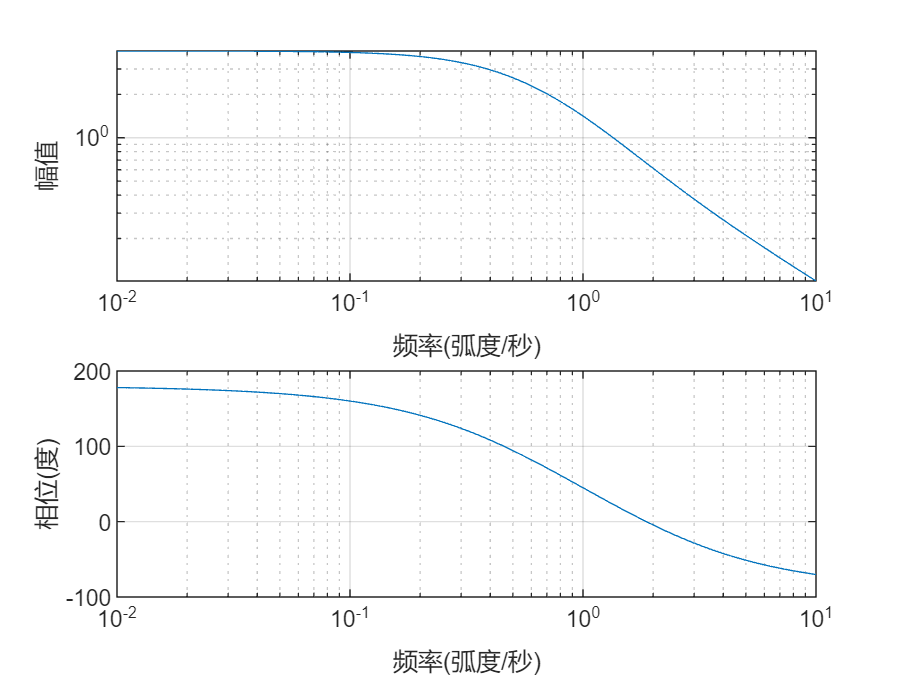

b1=[1 -2];
a1=[1 1.5 0.5];
freqs(b1,a1);

4.5 b 写出部分分式展开式

用 [r1 p1] = residue(b1,a1)

[r1,p1]=residue(b1,a1)

r1 =      6
    -5


p1 =    -1.0000
   -0.5000


部分分式展开式为 H1(jw) = 6 / (jw+1) - 5 / (jw+0.5)

4.5 c 写出单位冲激响应，判断是否可积

理论可直接发现，h1(t) = 6*exp(-t) - 5*exp(-0.5t)

syms t;%用符号变量，防止后续报错
h1=6*exp(-t)-5*exp(-0.5*t);
result=int(h1,t,0,inf);%从零到无穷积分
result

$$result = -4$$

能计算出积分，故可积

4.6 a 加载ctftmod.mat，画出Z的摩斯密码

load ctftmod.mat;
who


您的变量为:

Z      af     bf     dash   dot    f1     f2     m1     m1r    m2     m2r    m3     m3r    ndash  ndot   t      x      y      ydash  ydot   yo     



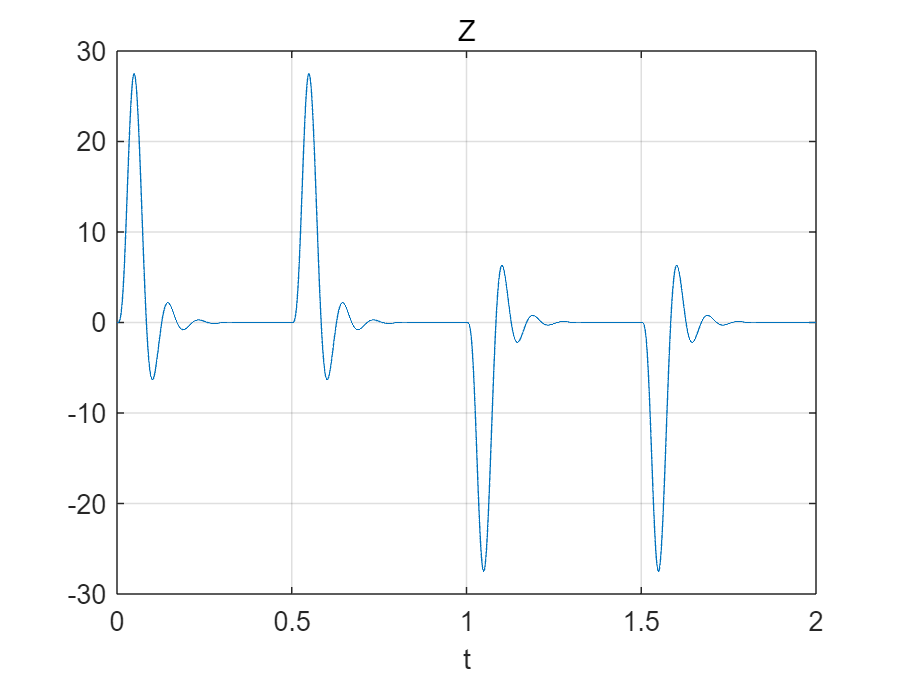

Z=[dash dash dot dot];
figure;
plot(t,Z),xlabel('t'),title('Z'),grid on;

4.6 b 画出频率响应

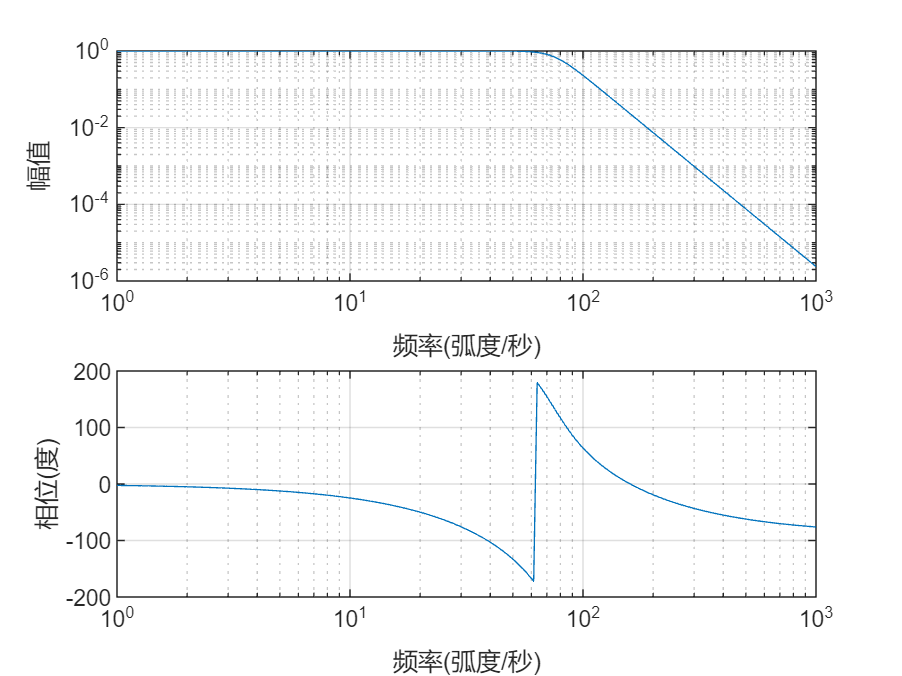

figure;
freqs(bf,af);

4.6 c 对两个信号滤波

根据提示使用lsim，然后画图比较

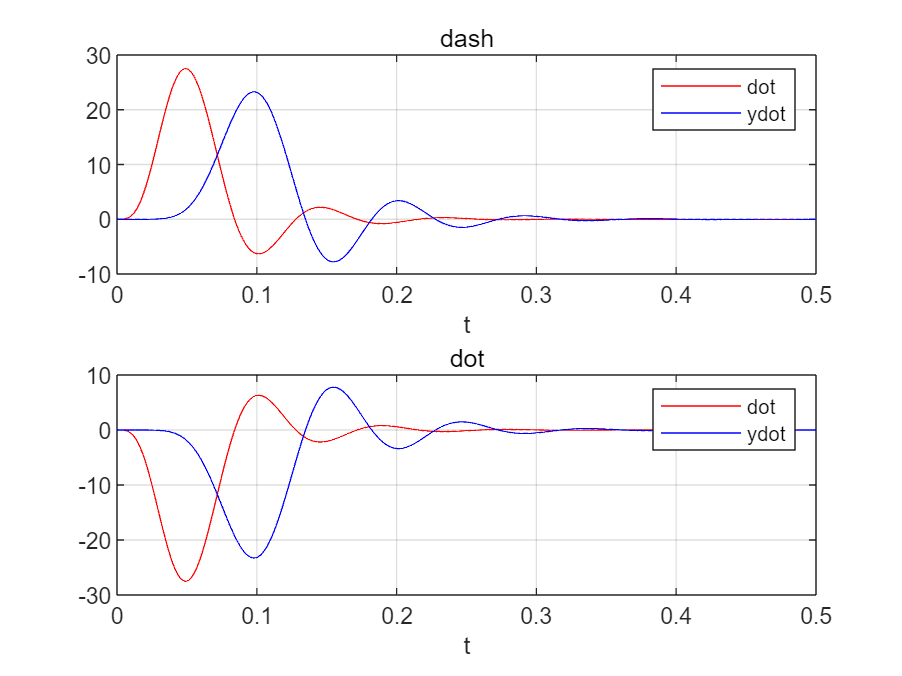

ydash=lsim(bf,af,dash,t(1:length(dash)));
ydot=lsim(bf,af,dot,t(1:length(dot)));
ndash=t(1:length(dash));
ndot=t(1:length(dot));
figure;
subplot(2,1,1),plot(ndash,dash,'r',ndash,ydash,'b'),xlabel('t'),legend('dot','ydot'),title('dash'),grid on;
subplot(2,1,2),plot(ndot,dot,'r',ndot,ydot,'b'),xlabel('t'),legend('dot','ydot'),title('dot'),grid on;

结果如图。

4.6 d 用cos(2pif1t)调制。

先改变信号，然后用lsim

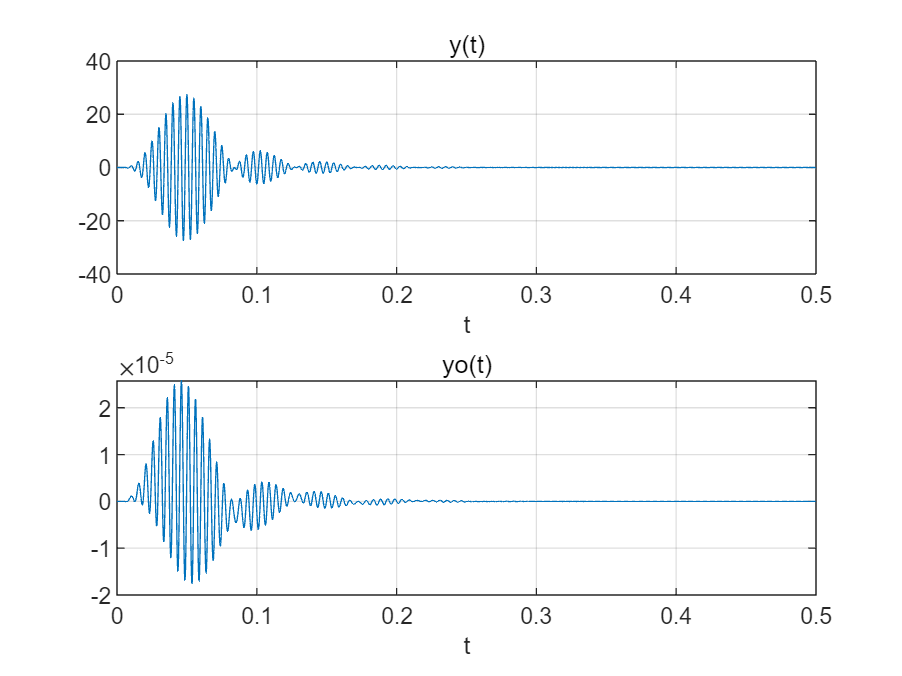

y=dash.*cos(2*pi*f1*t(1:length(dash)));
figure;
subplot(2,1,1),plot(t(1:length(y)),y),xlabel('t'),title('y(t)'),grid on;
yo=lsim(bf,af,y,t(1:length(y)));
subplot(2,1,2),plot(t(1:length(yo)),yo),xlabel('t'),title('yo(t)'),grid on;

波形与原来的ydash类似，但能量大幅损失。

4.6 e 求解傅里叶变换。

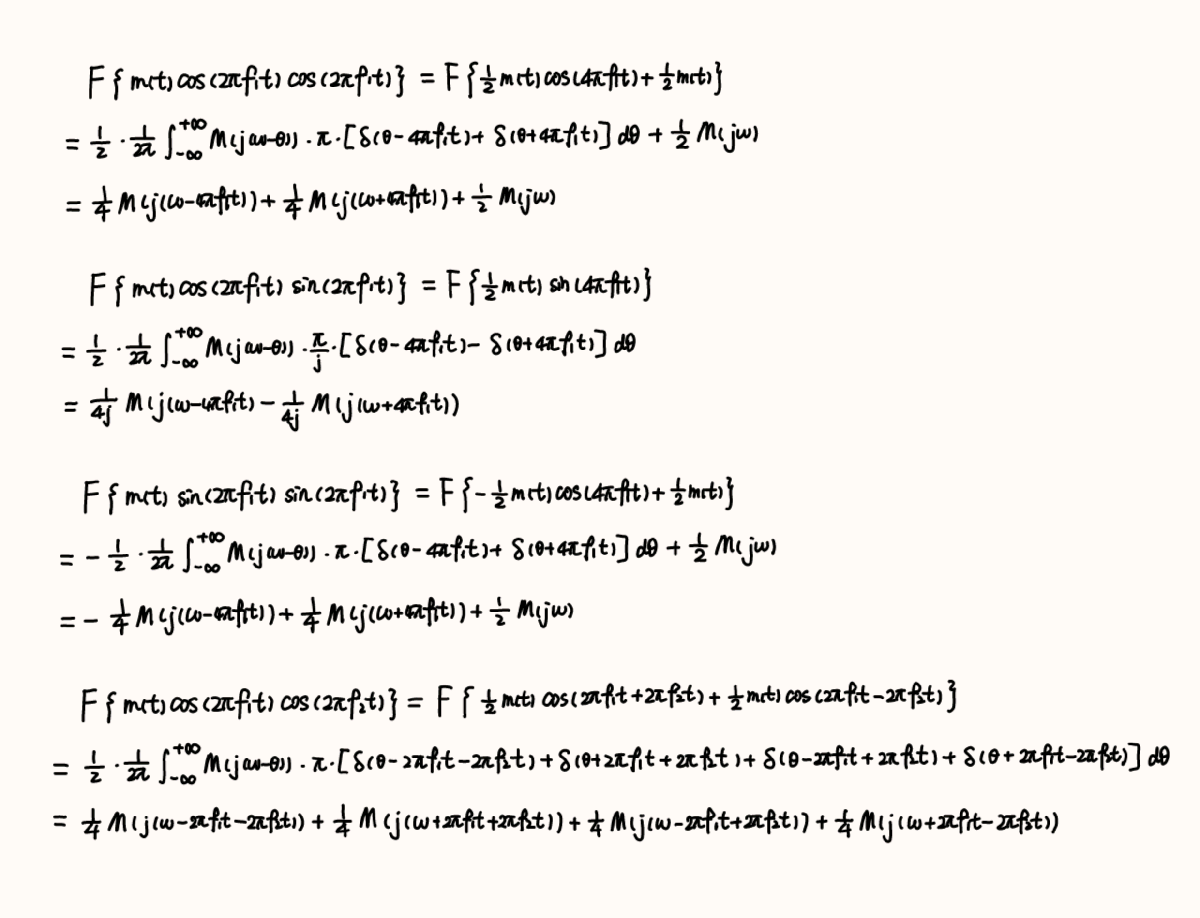

4.6 f 解调信号m1(t)，画出频率响应，判断信号。

x(t)=m1(t)*cos(2*pi*f1*t)+m2(t)*sin(2*pi*f2*t)+m3(t)*sin(2*pi*f1*t)

可以知道m1(t)由cos(2*pi*f1*t)调制。

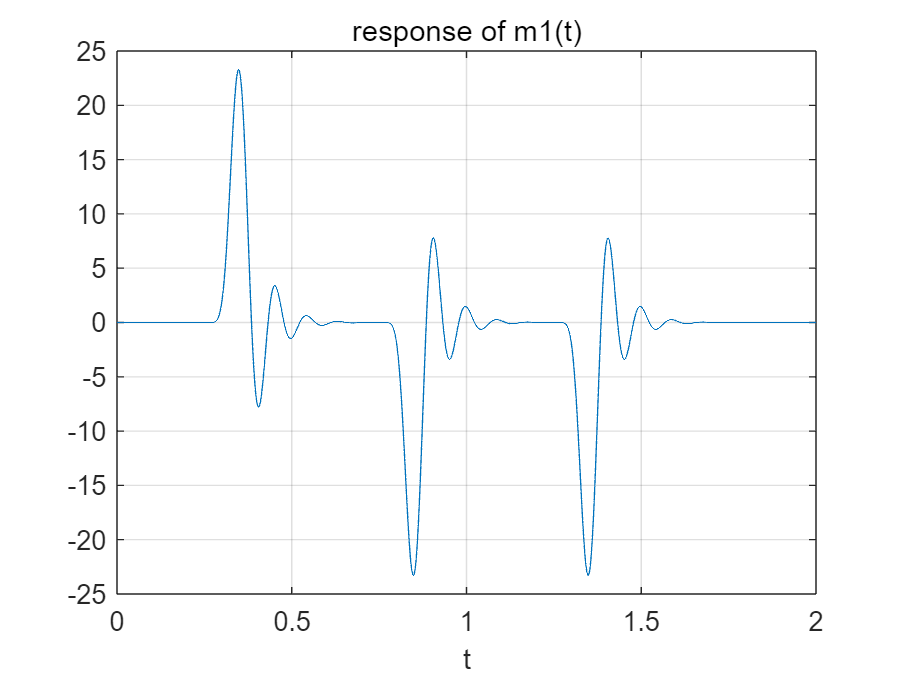

m1=x.*cos(2*pi*f1*t);
m1r=2*lsim(bf,af,m1,t);
figure;
plot(t(1:length(m1r)),m1r),xlabel('t'),title('response of m1(t)'),grid on;

观察图像可以知道，信号是 dash dot dot，对照表格，是D。

4.6 g 解调信号m2(t)，m3(t)，画出频率相应，判断信号。

x(t)=m1(t)*cos(2*pi*f1*t)+m2(t)*sin(2*pi*f2*t)+m3(t)*sin(2*pi*f1*t)

可以知道m2(t)由sin(2*pi*f2*t)调制，m3(t)由sin(2*pi*f1*t)调制。

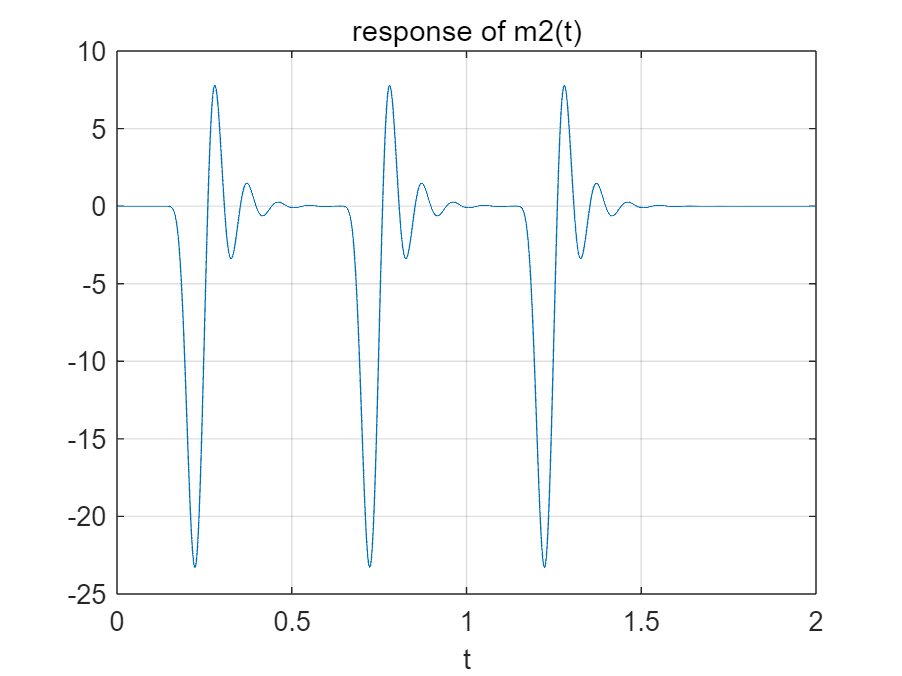

m2=x.*sin(2*pi*f2*t);
m2r=2*lsim(bf,af,m2,t);
figure;
plot(t(1:length(m2r)),m2r),xlabel('t'),title('response of m2(t)'),grid on;

观察图像可以知道，信号是 dot dot dot，对照表格，是S。

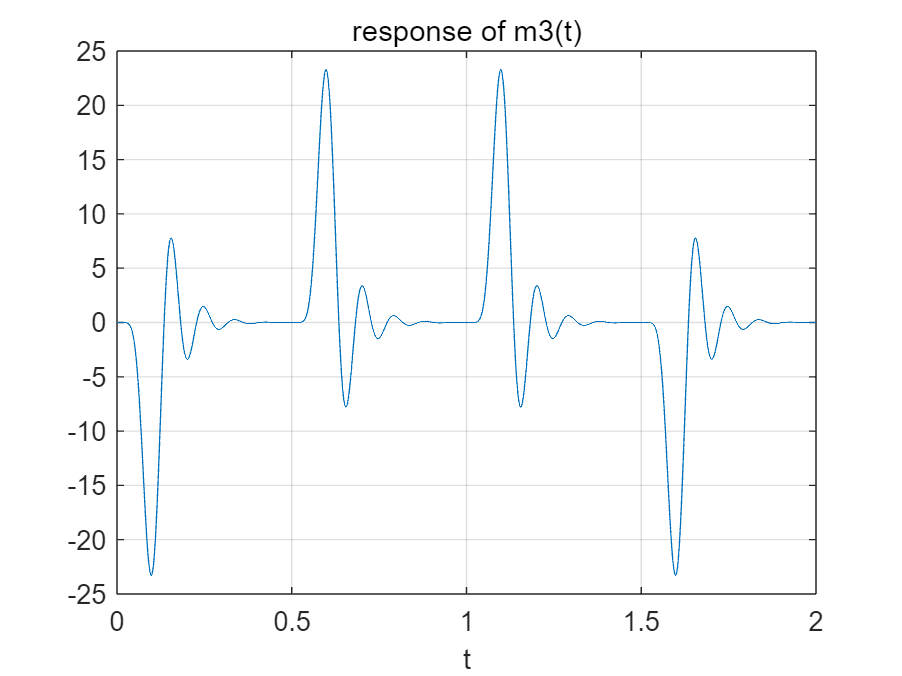

m3=x.*sin(2*pi*f1*t);
m3r=2*lsim(bf,af,m3,t);
figure;
plot(t(1:length(m3r)),m3r),xlabel('t'),title('response of m3(t)'),grid on;

观察图像可以知道，信号是 dot dash dash dot，对照表格，是P。

Agent007的遗言是：The future of technology lies in DSP.